# Trabajo práctico: Control en espacio de estados

## 1) Ubicación de polos por respuesta en el tiempo.

Se propone el control por ubicación de polos de un sistema de velocidad constante o velocidad crucero. El objetivo del control es seguir la velocidad de referencia proporcionada. La perturbación del sistema está dada por un cambio en el ángulo del terreno ($\alpha$).

El modelo matemático de la planta está dado por:

donde $\Delta x_{1}$ es la fuerza en las ruedas, $\Delta x_{2}$ es la velocidad en las ruedas, $\Delta u$ es la señal de entrada y $\Delta d_{1}$ es la perturbación.

El vehículo está viajando a 20 m/s sobre una ruta plana. La perturbación se considera nula.

En el siguiente modelo de control de velocidad crucero,

a) Verifique si el sistema es controlable.

b) Encuentre el valor de la matriz K para $\omega_{n} = 0.6$ y $\zeta = 1/\sqrt{2}$, donde $p(s) = s^{2} + 2\zeta\omega_{n} s + \omega_{n}^{2}$ es el polinomio característico deseado.

c) Encuentre el valor de kr.

d) Agregue la perturbación dada por el archivo roaddist.mat. Analice la respuesta del sistema. ¿Es satisfactoria?

e) ¿Qué conclusiones se derivan de la simulación de este modelo?

clear;

### Análisis de controlabilidad

A = [
    -1.25   0;
    5e-5    -0.0024
    ];
B = [20000; 0];
d = [0; -9.82]; % Matriz de perturbación
C = [0  1];

La matriz de controlabilidad será:

Ctr = [A A*B];
disp(Ctr);

   1.0e+04 *

   -0.0001         0   -2.5000
    0.0000   -0.0000    0.0001



disp(rank(Ctr));

     2



Dado que el rango es igual a 2, el sistema es **controlable**.

### Análisis de polos y ceros a lazo abierto

Cálculo de autovalores de matriz A:

lambdaA = eig(A);
disp(lambdaA);

   -0.0024
   -1.2500



Polinomio característico de la planta:

syms lambda;
I = eye(2);
p = det(lambda*I-A);
disp(simplify(p));

$$\frac{\left(4\,\lambda +5\right)\,\left(1250\,\lambda +3\right)}{5000}$$

disp(expand(p));

$$\lambda^{2}+\frac{3131\,\lambda }{2500}+\frac{3}{1000}$$

Coeficientes del polinomio característico:

Coef = fliplr(coeffs(p));  % Inversión, coeffs da los coeficientes de menor exponente a mayor

Función de transferencia de la planta:

H = tf(1, eval(Coef));     % Evaluación de los coeficientes porque siguen siendo simbólicos

Gráfica de polos y ceros:

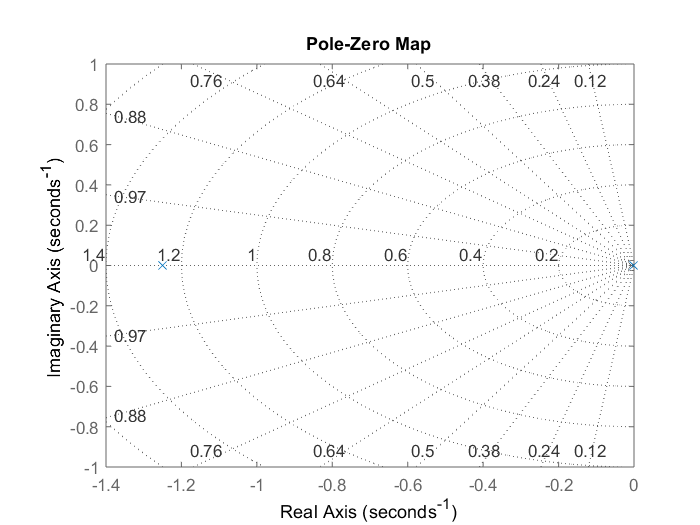

pzmap(H);
grid on;

Se puede observar que la planta posee polos reales negativos, distintos.

### Diseño de control a lazo cerrado

Siendo la ley de control:


$$u(t) = -Kx(t) + k_{r} r(t)$$


Entonces el modelo del sistema será de la forma:


$$\dot{x}(t) = (A - BK)x(t)$$


Por lo que la matriz principal del sistema es $(A - BK)$.

K = sym('k', [1 2]); % dim pxn p=1 n=2
disp(K);

$$\left(\begin{array}{cc} k_{1} & k_{2} \end{array}\right)$$

disp(A-B*K);

$$\left(\begin{array}{cc} -20000\,k_{1}-\frac{5}{4} & -20000\,k_{2}\\ \frac{1}{20000} & -\frac{3}{1250} \end{array}\right)$$

Cálculo de polinomio característico del sistema con matriz $(A - BK)$ de forma simbólica:

p = det(lambda*I-(A-B*K));
disp(p);

$$48\,k_{1}+k_{2}+\frac{3131\,\lambda }{2500}+20000\,k_{1}\,\lambda +\lambda^{2}+\frac{3}{1000}$$

### Cálculo de matriz K

Comparándolo con el polinomio deseado:

syms zeta omega_n;
p_deseado = lambda^2 + 2*zeta*omega_n*lambda + omega_n^2;
disp(p_deseado);

$$\lambda^{2}+2\,\zeta \,\lambda \,\omega_{n}+{\omega_{n}}^{2}$$

Obtención de coeficientes del polinomio característico del sistema:

Coef_p = fliplr(coeffs(p, lambda)); % Coeficientes respecto a lambda (o variable s)
disp(Coef_p);

$$\left(\begin{array}{ccc} 1 & 20000\,k_{1}+\frac{3131}{2500} & 48\,k_{1}+k_{2}+\frac{3}{1000} \end{array}\right)$$

Obtención de coeficientes del polinomio característico deseado:

Coef_pd = fliplr(coeffs(p_deseado, lambda));
disp(Coef_pd);

$$\left(\begin{array}{ccc} 1 & 2\,\omega_{n}\,\zeta & {\omega_{n}}^{2} \end{array}\right)$$

Igualando los coeficientes se obtiene las siguientes expresiones:

eqn = Coef_p == Coef_pd;
disp(eqn);

$$\left(\begin{array}{ccc} 1=1 & 20000\,k_{1}+\frac{3131}{2500}=2\,\omega_{n}\,\zeta & 48\,k_{1}+k_{2}+\frac{3}{1000}={\omega_{n}}^{2} \end{array}\right)$$

S = solve(eqn, K);
disp(S.k1);

$$\frac{\omega_{n}\,\zeta }{10000}-\frac{3131}{50000000}$$

disp(S.k2);

$${\omega_{n}}^{2}-\frac{3\,\zeta \,\omega_{n}}{625}+\frac{9}{1562500}$$

Evaluando las expresiones con los valores dados de $\omega_{n}$ y $\zeta$, se obtiene la matriz K:

omega_n = 0.6;
zeta = 1 / sqrt(2);
k1 = eval(subs(S.k1));
k2 = eval(subs(S.k2));
disp("k1 = " + k1);

k1 = -2.0194e-05


disp("k2 = " + k2);

k2 = 0.35797


K = [k1 k2];

### Cálculo de $k_{r}$:

Siendo:


$$k_{r} = -1/C(A-BK)^{-1}B$$


kr = -inv(C*inv(A-B*K)*B);
disp(kr);

    0.3600



Evaluando con los valores de la matriz K obtenidos:

kr = eval(subs(kr));
disp(kr);

    0.3600



### Perturbación $\Delta d_{1}$ en 'roaddist.mat'

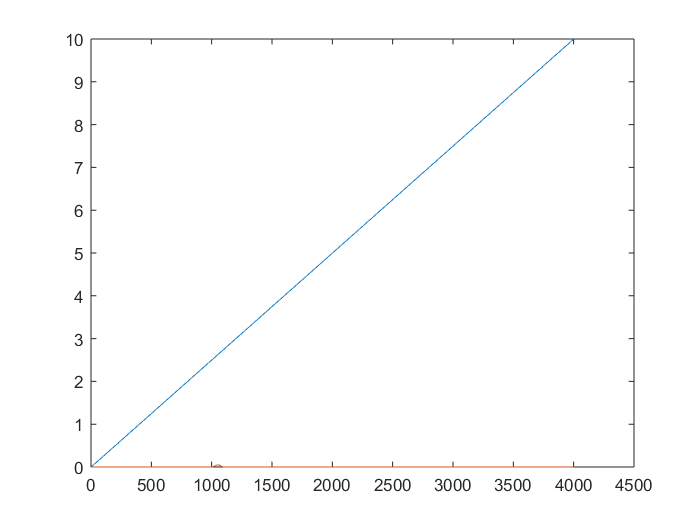

load('roaddist.mat');
plot(roaddist);

perturb = [roaddist(:, 1) -roaddist(:, 1) -roaddist(:, 1)];